#### This lesson is for summary and reduce the code explained in previous lessons.

First of all we need to define initial and goal poses.

initPose = [ 0.5; 0.5; 1.5707]; % [x ; y ; theta]   
goalPose = [2; 2.5;0];

Define differential robot and visualizer.

R = 0.1; 
L = 0.12; 
mobileRobot = DifferentialDrive(R,L);
viz = Visualizer2D;
viz.robotRadius = L; 

generateAugmentedMap is a function that given parameters returns  a map and  augmented map for [path planning ](matlab:open('../3_PathPlanning/PathPlanning.mlx'))  (The purpose of this function is for cleaner code)

[map, mapDilatation]  = generateAugmentedMap(which('world1.png'), 0.1, 10, L); %[path, treshold, scale,robotRadio]
viz.mapName = 'map';

getPathRRT generate apath  (The purpose of this function is for cleaner code)

[pthObj, solnInfo] = getPathRRT(mapDilatation,initPose,goalPose,0.2,.1,0.2,30000); %[map,initPose,goalPose,MinTurningRadius,ValidationDistance,MaxConnectionDistance,MaxIterations]

controllerPP define a Pure pursuit controller as we saw in [previous lesson](matlab:open('../3_PathPlanning/PathTracking.mlx')) (The purpose of this function is for cleaner code)

[controller] = controllerPP(pthObj,0.05,0.1,pi/6);%[pthObj,LookaheadDistance,DesiredLinearVelocity,MaxAngularVelocity]

Execute simulation.

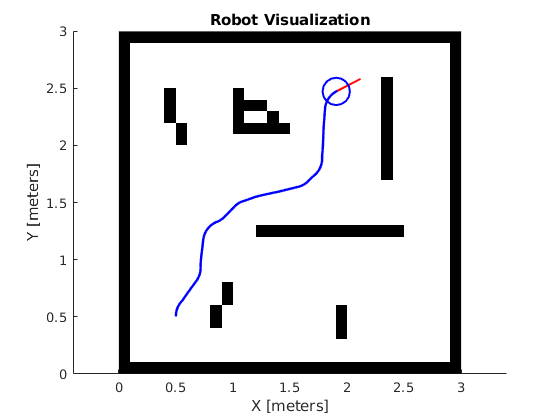

currentPose = initPose;
[sampleTime,tVec,r] = simulTime(0.1,38);
for idx = 2:numel(tVec) 
    
    if( sqrt( (currentPose(1)-pthObj.States(end,1))^2 + (currentPose(2)-pthObj.States(end,2))^2 )  < L/2  )
       break
    end
    
    [vRef,wRef,lookAheadPt] = controller(currentPose);
    bodyV = [vRef;0;wRef];
    
    % Convert from robot body to world
    vel =  bodyToWorld(bodyV,currentPose);  
   
    % Perform forward discrete integration step
    currentPose = currentPose + vel * sampleTime; 
    
    % Update visualization
    viz(currentPose);

    %Wait for visualization rate
    waitfor(r);
    
end